# Split half 1st half vs 2nd half

root_dir = 'C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\nirs';

% Load all .nirs files
raw = nirs.io.loadDirectory(root_dir, {'subject'});

% Check available stims before doing anything
available_stims = nirs.getStimNames(raw);
disp('Available stim names:');
disp(available_stims);

% Keep only relevant stims
j = nirs.modules.KeepStims();
j.listOfStims = {'stim_channel1', 'stim_channel2'};
raw = j.run(raw);

% Rename stim channels
j = nirs.modules.RenameStims();
j.listOfChanges = {
   'stim_channel1', '1';
   'stim_channel2', '1';
};
raw = j.run(raw);

% Check new stim names
disp('Stim names after renaming:');
disp(nirs.getStimNames(raw));

% Set all stim durations to 36 seconds
stimNames = unique(nirs.getStimNames(raw));
for s = 1:length(stimNames)
    raw = nirs.design.change_stimulus_duration(raw, stimNames{s}, 36);
end

% Trim each recording to only the first half
for i = 1:length(raw)
    maxTime = raw(i).time(end);
    midpoint = maxTime / 2;
    
    % Trim the time series
    keep_idx = raw(i).time <= midpoint;
    raw(i).data = raw(i).data(keep_idx, :);
    raw(i).time = raw(i).time(keep_idx);

    % Trim stimulus events too
    stimNames = fieldnames(raw(i).stimulus);
    for s = 1:length(stimNames)
        stimname = stimNames{s};
        stim_table = raw(i).stimulus.(stimname);
        if istable(stim_table) && any(strcmp('onset', stim_table.Properties.VariableNames))
            raw(i).stimulus.(stimname) = stim_table(stim_table.onset <= midpoint, :);
        end
    end
end

% QT-NIRS quality assessment
j = nirs.modules.QT();
j.qThreshold = 0.7;
j.fCut = [0.5 2.5];
j.sciThreshold = 0.6;
j.pspThreshold = 0.1;
ScansQuality = j.run(raw);

% Preprocessing
j = nirs.modules.Resample(); j.Fs = 1.5;
raw = j.run(raw);

j = nirs.modules.OpticalDensity(); raw = j.run(raw);
j = nirs.modules.TDDR(); raw = j.run(raw);
j = nirs.modules.BeerLambertLaw(); hb = j.run(raw);

% Prune bad channels based on QT-NIRS output
Hb_pruned = hb;
for i = 1:length(hb)
    hb(i) = hb(i).sorted({'source', 'detector', 'type'});
    bad_idx = find(ScansQuality(i).qMats.MeasListAct == 0);
    fprintf('Scan: %i | #BadChannels: %i\n', i, length(bad_idx)/2);
    Hb_pruned(i).data(:, bad_idx) = NaN;
end

% label short channels
j = nirs.modules.LabelShortSeperation();
Hb_pruned = j.run(Hb_pruned)

% Apply prewhitening using AR-IRLS - no short channels 
j = nirs.modules.AR_IRLS();
SubjStats = j.run(Hb_pruned);

disp(SubjStats.table());
p3 = SubjStats.table()

% Save the table to a CSV file
outputFile = '1st_half_glm_result_subjectlevel_tvr_clean.csv';            % Specify the output file name
writetable(p3, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);


%% Compute subject-level contrast: condition 1 vs 2
% Define the contrast vector
contrast = [1 -1];  % condition 1 > condition 2

contrast_results = [];
for i = 1:length(SubjStats)
    c = SubjStats(i).ttest(contrast);
    tbl = c.table();
    tbl.subject = repmat(string(SubjStats(i).description), height(tbl), 1);
    contrast_results = [contrast_results; tbl];
end

% Display final subject-level contrast table
%contrast_output = contrast_results(:, {'subject', 'channel', 'type', 'beta', 'tstat', 'p'});
disp(contrast_results);

% Save contrast results
writetable(contrast_results, '1st_half_subject_level_contrasts_clean.csv');
disp('Contrast results saved to 1st_half_subject_level_contrasts.csv');


%use chroma and channel as fixed effects not group (no group)
j = nirs.modules.MixedEffects();
j.formula = 'beta ~ -1 + cond + (1|subject)';
j.dummyCoding = 'full';
GroupStats = j.run(SubjStats);

disp(GroupStats.table());
p1 = GroupStats.table()

% Save the table to a CSV file
outputFile = '1st_half_GLM_GROUP_tvr_clean.csv';            % Specify the output file name
writetable(p1, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);

GroupStats.draw('tstat', [-5 5], 'p < 0.05')


% Contrast: Condition 2 vs Condition 1
c2_vs_1 = [-1, 1, 0]; % Contrast vector for condition 2 vs. condition 1
ContrastStats2_vs_1 = GroupStats.ttest(c2_vs_1);
ContrastStats2_vs_1.draw('tstat', [-5 5], 'p < 0.05');

disp(ContrastStats2_vs_1.table());
p5 = ContrastStats2_vs_1.table()

% Save the table to a CSV file
outputFile = '1st_half_contrast_clean.csv';            % Specify the output file name
writetable(p5, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);

## Second Half

root_dir = 'C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\nirs';

% Load .nirs files
raw = nirs.io.loadDirectory(root_dir, {'subject'});

% Trim each file to only keep the second half of the recording
for i = 1:length(raw)
    full_time = raw(i).time(end) - raw(i).time(1);
    midpoint = raw(i).time(1) + full_time / 2;

    % Crop data and stimulus
    raw(i).data = raw(i).data(raw(i).time > midpoint, :);
    raw(i).time = raw(i).time(raw(i).time > midpoint);

    stim_names = fieldnames(raw(i).stimulus);
    for s = 1:length(stim_names)
        stimname = stim_names{s};
        stim_table = raw(i).stimulus.(stimname);

        % Keep only stim with onset in second half
        if isfield(stim_table, 'onset')
            raw(i).stimulus.(stimname) = stim_table(stim_table.onset > midpoint, :);
        end
    end
end

% Display stim names
available_stims = nirs.getStimNames(raw);
disp('Available stim names:');
disp(available_stims);

% Keep desired stimulus channels
j = nirs.modules.KeepStims();
j.listOfStims = {'stim_channel1', 'stim_channel2'};  % Update if needed
raw = j.run(raw);

% Rename stim channels
j = nirs.modules.RenameStims();
j.listOfChanges = {
   'stim_channel1', '1';
   'stim_channel2', '1';
};
raw = j.run(raw);
disp('Stim names after renaming:');
disp(nirs.getStimNames(raw));

% Set duration for all stimuli
stimNames = unique(nirs.getStimNames(raw));
for s = 1:length(stimNames)
    raw = nirs.design.change_stimulus_duration(raw, stimNames{s}, 36);
end

% Run QT-NIRS for quality check
j = nirs.modules.QT();
j.qThreshold = 0.7; j.fCut = [0.5 2.5]; j.sciThreshold = 0.6; j.pspThreshold = 0.1;
ScansQuality = j.run(raw);

% Preprocessing pipeline
j = nirs.modules.Resample(); j.Fs = 1.5; raw = j.run(raw);
j = nirs.modules.OpticalDensity(); raw = j.run(raw);
j = nirs.modules.TDDR(); raw = j.run(raw);
j = nirs.modules.BeerLambertLaw(); hb = j.run(raw);

% Channel pruning based on QT
Hb_pruned = hb;
for i = 1:length(hb)
    hb(i) = hb(i).sorted({'source', 'detector', 'type'});
    bad_idx = find(ScansQuality(i).qMats.MeasListAct == 0);
    fprintf('Scan:%i #BadChannels:%i\n', i, length(bad_idx)/2);
    Hb_pruned(i).data(:, bad_idx) = NaN;
end
% label short channels
j = nirs.modules.LabelShortSeperation();
Hb_pruned = j.run(Hb_pruned)

% Apply prewhitening using AR-IRLS - no short channels 
j = nirs.modules.AR_IRLS();
SubjStats = j.run(Hb_pruned);

disp(SubjStats.table());
p3 = SubjStats.table()

% Save the table to a CSV file
outputFile = '2nd_half_glm_result_subjectlevel_tvr_clean.csv';            % Specify the output file name
writetable(p3, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);


%% Compute subject-level contrast: condition 1 vs 2
% Define the contrast vector
contrast = [1 -1];  % condition 1 > condition 2

contrast_results = [];
for i = 1:length(SubjStats)
    c = SubjStats(i).ttest(contrast);
    tbl = c.table();
    tbl.subject = repmat(string(SubjStats(i).description), height(tbl), 1);
    contrast_results = [contrast_results; tbl];
end

% Display final subject-level contrast table
%contrast_output = contrast_results(:, {'subject', 'channel', 'type', 'beta', 'tstat', 'p'});
disp(contrast_results);

% Save contrast results
writetable(contrast_results, '2nd_half_subject_level_contrasts_clean.csv');
disp('Contrast results saved to 2nd_half_subject_level_contrasts.csv');


%use chroma and channel as fixed effects not group (no group)
j = nirs.modules.MixedEffects();
j.formula = 'beta ~ -1 + cond + (1|subject)';
j.dummyCoding = 'full';
GroupStats = j.run(SubjStats);

disp(GroupStats.table());
p1 = GroupStats.table()

% Save the table to a CSV file
outputFile = '2nd_half_GLM_GROUP_tvr_clean.csv';            % Specify the output file name
writetable(p1, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);

GroupStats.draw('tstat', [-5 5], 'p < 0.05')


% Contrast: Condition 2 vs Condition 1
c2_vs_1 = [-1, 1, 0]; % Contrast vector for condition 2 vs. condition 1
ContrastStats2_vs_1 = GroupStats.ttest(c2_vs_1);
ContrastStats2_vs_1.draw('tstat', [-5 5], 'p < 0.05');

disp(ContrastStats2_vs_1.table());
p5 = ContrastStats2_vs_1.table()

% Save the table to a CSV file
outputFile = '2nd_half_contrast_clean.csv';            % Specify the output file name
writetable(p5, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);

## split even/odd blocks

%% ODD blocks – correct code

root_dir = 'C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\nirs';

% Load all .nirs files
raw = nirs.io.loadDirectory(root_dir, {'subject'});

% Keep only relevant stims
j = nirs.modules.KeepStims();
j.listOfStims = {'stim_channel1', 'stim_channel2'};
raw = j.run(raw);

% Rename stim channels
j = nirs.modules.RenameStims();
j.listOfChanges = {
    'stim_channel1', '1';
    'stim_channel2', '2';
};
raw = j.run(raw);

% Set all stim durations to 36 seconds
stimNames = unique(nirs.getStimNames(raw));
for s = 1:length(stimNames)
    raw = nirs.design.change_stimulus_duration(raw, stimNames{s}, 36);
end

% Remove every second onset (keep odd-numbered) for each stimulus
for i = 1:length(raw)
    for stimIdx = 1:length(stimNames)
        stimName = stimNames{stimIdx};
        stimObj = raw(i).stimulus(stimName);
        if ~isempty(stimObj)
            % Extract and sort onsets
            [sortedOnsets, sortIdx] = sort(stimObj.onset);
            % Access duration and amplitude using object-specific syntax
            allDurations = arrayfun(@(n) stimObj.dur(n), sortIdx);
            allAmplitudes = arrayfun(@(n) stimObj.amp(n), sortIdx);

            % Keep only odd-numbered events
            keepIdx = 1:2:length(sortedOnsets);

            % Reconstruct stimulus object
            newStim = nirs.design.StimulusEvents();
            newStim.onset = sortedOnsets(keepIdx);
            newStim.dur = allDurations(keepIdx);
            newStim.amp = allAmplitudes(keepIdx);

            % Replace the stimulus in the raw object
            raw(i).stimulus(stimName) = newStim;
        end
    end
end

% QT-NIRS quality assessment
j = nirs.modules.QT();
j.qThreshold = 0.7;
j.fCut = [0.5 2.5];
j.sciThreshold = 0.6;
j.pspThreshold = 0.1;
ScansQuality = j.run(raw);

% Preprocessing
j = nirs.modules.Resample(); j.Fs = 1.5;
raw = j.run(raw);

j = nirs.modules.OpticalDensity(); 
raw = j.run(raw);
j = nirs.modules.TDDR(); 
raw = j.run(raw);
j = nirs.modules.BeerLambertLaw();
hb = j.run(raw);

%CHANNEL PRUNING based on QTNIRS results
Hb_pruned = hb;
for i=1:length(raw)
   hb(i) = hb(i).sorted({'source', 'detector', 'type'});
   idxBadCh = find(ScansQuality(i).qMats.MeasListAct==0);
   fprintf('Scan:%i #BadChannels:%i\n',i,length(idxBadCh)/2);
   Hb_pruned(i).data(:,idxBadCh) = nan;
end

% Label short channels
j = nirs.modules.LabelShortSeperation();
Hb_pruned = j.run(Hb_pruned);

% Apply prewhitening using AR-IRLS
j = nirs.modules.AR_IRLS();
SubjStats = j.run(Hb_pruned);

% Save results
p3 = SubjStats.table();
outputFile = 'odd_blocks_glm_result_subjectlevel_tvr_clean.csv';
writetable(p3, outputFile);
disp(['GLM results saved to ', outputFile]);


%% Compute subject-level contrast: condition 1 vs 2
% Define the contrast vector
contrast = [1 -1];  % condition 1 > condition 2

contrast_results = [];
for i = 1:length(SubjStats)
    c = SubjStats(i).ttest(contrast);
    tbl = c.table();
    tbl.subject = repmat(string(SubjStats(i).description), height(tbl), 1);
    contrast_results = [contrast_results; tbl];
end

% Display final subject-level contrast table
%contrast_output = contrast_results(:, {'subject', 'channel', 'type', 'beta', 'tstat', 'p'});
disp(contrast_results);

% Save contrast results
writetable(contrast_results, 'odd_subject_level_contrasts_clean.csv');
disp('Contrast results saved to odd_subject_level_contrasts.csv');


j = nirs.modules.MixedEffects();
j.formula = 'beta ~ -1 + cond + (1|subject)';
j.dummyCoding = 'full';
GroupStats = j.run(SubjStats);

disp(GroupStats.table());
p1 = GroupStats.table();

% Save results
outputFile = 'odd_blocks_GLM_GROUP_tvr_clean.csv';
writetable(p1, outputFile);
disp(['GLM results saved to ', outputFile]);

GroupStats.draw('tstat', [-5 5], 'p < 0.05');


% Contrast: Condition 2 vs Condition 1
c2_vs_1 = [-1, 1, 0]; % Contrast vector for condition 2 vs. condition 1
ContrastStats2_vs_1 = GroupStats.ttest(c2_vs_1);
ContrastStats2_vs_1.draw('tstat', [-5 5], 'p < 0.05');

disp(ContrastStats2_vs_1.table());
p5 = ContrastStats2_vs_1.table()

% Save the table to a CSV file
outputFile = 'odd_contrast_clean.csv';            % Specify the output file name
writetable(p5, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);

## EVEN BLOCKS -


root_dir = 'C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\nirs';

% Load all .nirs files
raw = nirs.io.loadDirectory(root_dir, {'subject'});

% Keep only relevant stims
j = nirs.modules.KeepStims();
j.listOfStims = {'stim_channel1', 'stim_channel2'};
raw = j.run(raw);

% Rename stim channels
j = nirs.modules.RenameStims();
j.listOfChanges = {
    'stim_channel1', '1';
    'stim_channel2', '1';
};
raw = j.run(raw);

% Set all stim durations to 36 seconds
stimNames = unique(nirs.getStimNames(raw));
for s = 1:length(stimNames)
    raw = nirs.design.change_stimulus_duration(raw, stimNames{s}, 36);
end

% Keep only even-numbered events (2nd, 4th, 6th, ...) for each stimulus
for i = 1:length(raw)
    for stimIdx = 1:length(stimNames)
        stimName = stimNames{stimIdx};
        stimObj = raw(i).stimulus(stimName);
        if ~isempty(stimObj)
            [sortedOnsets, sortIdx] = sort(stimObj.onset);
            allDurations = arrayfun(@(n) stimObj.dur(n), sortIdx);
            allAmplitudes = arrayfun(@(n) stimObj.amp(n), sortIdx);

            keepIdx = 2:2:length(sortedOnsets);  % <- changed line

            newStim = nirs.design.StimulusEvents();
            newStim.onset = sortedOnsets(keepIdx);
            newStim.dur = allDurations(keepIdx);
            newStim.amp = allAmplitudes(keepIdx);

            raw(i).stimulus(stimName) = newStim;
        end
    end
end

% QT-NIRS quality assessment
j = nirs.modules.QT();
j.qThreshold = 0.7;
j.fCut = [0.5 2.5];
j.sciThreshold = 0.6;
j.pspThreshold = 0.1;
ScansQuality = j.run(raw);

% Preprocessing
j = nirs.modules.Resample(); j.Fs = 1.5;
raw = j.run(raw);

j = nirs.modules.OpticalDensity(); raw = j.run(raw);
j = nirs.modules.TDDR(); raw = j.run(raw);
j = nirs.modules.BeerLambertLaw(); hb = j.run(raw);

%CHANNEL PRUNING based on QTNIRS results
Hb_pruned = hb;
for i=1:length(raw)
   hb(i) = hb(i).sorted({'source', 'detector', 'type'});
   idxBadCh = find(ScansQuality(i).qMats.MeasListAct==0);
   fprintf('Scan:%i #BadChannels:%i\n',i,length(idxBadCh)/2);
   Hb_pruned(i).data(:,idxBadCh) = nan;
end

% Label short channels
j = nirs.modules.LabelShortSeperation();
Hb_pruned = j.run(Hb_pruned);

% Run GLM
j = nirs.modules.AR_IRLS();
SubjStats = j.run(Hb_pruned);

% Save results
p3 = SubjStats.table();
outputFile = 'even_glm_result_subjectlevel_tvr_clean.csv';
writetable(p3, outputFile);
disp(['GLM results saved to ', outputFile]);


%% Compute subject-level contrast: condition 1 vs 2
% Define the contrast vector
contrast = [1 -1];  % condition 1 > condition 2

contrast_results = [];
for i = 1:length(SubjStats)
    c = SubjStats(i).ttest(contrast);
    tbl = c.table();
    tbl.subject = repmat(string(SubjStats(i).description), height(tbl), 1);
    contrast_results = [contrast_results; tbl];
end

% Display final subject-level contrast table
%contrast_output = contrast_results(:, {'subject', 'channel', 'type', 'beta', 'tstat', 'p'});
disp(contrast_results);

% Save contrast results
writetable(contrast_results, 'even_subject_level_contrasts_clean.csv');
disp('Contrast results saved to even_subject_level_contrasts.csv');


j = nirs.modules.MixedEffects();
j.formula = 'beta ~ -1 + cond + (1|subject)';
j.dummyCoding = 'full';
GroupStats = j.run(SubjStats);

disp(GroupStats.table());
p1 = GroupStats.table();

% Save results
outputFile = 'even_blocks_GLM_GROUP_tvr_clean.csv';
writetable(p1, outputFile);
disp(['GLM results saved to ', outputFile]);

GroupStats.draw('tstat', [-5 5], 'p < 0.05');


% Contrast: Condition 2 vs Condition 1
c2_vs_1 = [-1, 1, 0]; % Contrast vector for condition 2 vs. condition 1
ContrastStats2_vs_1 = GroupStats.ttest(c2_vs_1);
ContrastStats2_vs_1.draw('tstat', [-5 5], 'p < 0.05');

disp(ContrastStats2_vs_1.table());
p5 = ContrastStats2_vs_1.table()

% Save the table to a CSV file
outputFile = 'even_contrast_clean.csv';            % Specify the output file name
writetable(p5, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);

## ODD EVEN SPLIT ROI AGGREGATION

## ODD BLOCKS

root_dir = 'C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\nirs';

% Load all .nirs files
raw = nirs.io.loadDirectory(root_dir, {'subject'});

% Keep only relevant stims
j = nirs.modules.KeepStims();
j.listOfStims = {'stim_channel1', 'stim_channel2'};
raw = j.run(raw);

% Rename stim channels
j = nirs.modules.RenameStims();
j.listOfChanges = {
    'stim_channel1', '1';
    'stim_channel2', '1';
};
raw = j.run(raw);

% Set all stim durations to 36 seconds
stimNames = unique(nirs.getStimNames(raw));
for s = 1:length(stimNames)
    raw = nirs.design.change_stimulus_duration(raw, stimNames{s}, 36);
end

% Remove every second onset (keep odd-numbered) for each stimulus
for i = 1:length(raw)
    for stimIdx = 1:length(stimNames)
        stimName = stimNames{stimIdx};
        stimObj = raw(i).stimulus(stimName);
        if ~isempty(stimObj)
            % Extract and sort onsets
            [sortedOnsets, sortIdx] = sort(stimObj.onset);
            % Access duration and amplitude using object-specific syntax
            allDurations = arrayfun(@(n) stimObj.dur(n), sortIdx);
            allAmplitudes = arrayfun(@(n) stimObj.amp(n), sortIdx);

            % Keep only odd-numbered events
            keepIdx = 1:2:length(sortedOnsets);

            % Reconstruct stimulus object
            newStim = nirs.design.StimulusEvents();
            newStim.onset = sortedOnsets(keepIdx);
            newStim.dur = allDurations(keepIdx);
            newStim.amp = allAmplitudes(keepIdx);

            % Replace the stimulus in the raw object
            raw(i).stimulus(stimName) = newStim;
        end
    end
end

% QT-NIRS quality assessment
j = nirs.modules.QT();
j.qThreshold = 0.7;
j.fCut = [0.5 2.5];
j.sciThreshold = 0.6;
j.pspThreshold = 0.1;
ScansQuality = j.run(raw);

% Preprocessing
j = nirs.modules.Resample(); j.Fs = 1.5;
raw = j.run(raw);

j = nirs.modules.OpticalDensity(); raw = j.run(raw);
j = nirs.modules.TDDR(); raw = j.run(raw);
j = nirs.modules.BeerLambertLaw(); hb = j.run(raw);

% Prune bad channels based on QT-NIRS output
Hb_pruned = hb;
for i = 1:length(hb)
    hb(i) = hb(i).sorted({'source', 'detector', 'type'});
    bad_idx = find(ScansQuality(i).qMats.MeasListAct == 0);
    fprintf('Scan: %i | #BadChannels: %i\n', i, length(bad_idx)/2);
    Hb_pruned(i).data(:, bad_idx) = NaN;
end

% Label short channels
j = nirs.modules.LabelShortSeperation();
Hb_pruned = j.run(Hb_pruned);

% --- ROI Aggregation ---
roi_definitions = struct( ...
    'Left_RLPFC', [1 1; 1 2; 2 1; 2 2], ...
    'Left_DLPFC', [4 3; 4 2; 4 4; 5 3; 5 4; 2 3], ...
    'Left_VLPFC', [3 1; 3 3], ...
    'Left_Sup_Parietal', [12 8; 12 10; 13 10], ...
    'Left_Inf_Parietal', [11 9; 11 8; 13 8; 13 9; 13 11], ...
    'Right_RLPFC', [6 5; 6 6; 7 5; 7 6], ...
    'Right_DLPFC', [7 7; 8 5; 8 7; 10 7], ...
    'Right_VLPFC', [9 7; 9 6], ...
    'Right_Sup_Parietal', [14 12; 14 13; 14 21; 16 13], ...
    'Right_Inf_Parietal', [15 12; 15 14; 16 12; 16 14; 16 15] ...
);

% ROI-specific dummy source-detector assignments for proper plotting
roi_sd_lookup = struct( ...
    'Left_RLPFC', [2, 2], ...
    'Left_DLPFC', [4, 3], ...
    'Left_VLPFC', [3, 1], ...
    'Left_Sup_Parietal', [12, 10], ...
    'Left_Inf_Parietal', [11, 9], ...
    'Right_RLPFC', [7, 5], ...
    'Right_DLPFC', [8, 7], ...
    'Right_VLPFC', [9, 6], ...
    'Right_Sup_Parietal', [14, 13], ...
    'Right_Inf_Parietal', [15, 14] ...
);

for i = 1:length(Hb_pruned)
    dat = Hb_pruned(i);
    new_data = [];
    roi_labels = {};
    sources = [];
    detectors = [];

    for roi = fieldnames(roi_definitions)'
        roi_name = roi{1};
        pairs = roi_definitions.(roi_name);
        roi_ts = nan(size(dat.data, 1), size(pairs, 1));

        for p = 1:size(pairs, 1)
            src = pairs(p, 1);
            det = pairs(p, 2);
            idx = find(dat.probe.link.source == src & ...
                       dat.probe.link.detector == det & ...
                       strcmpi(dat.probe.link.type, 'hbo'));
            if ~isempty(idx)
                roi_ts(:, p) = dat.data(:, idx(1));
            end
        end

        % Average across channels in the ROI
        new_data = [new_data, nanmean(roi_ts, 2)];
        roi_labels = [roi_labels, roi_name];

        % Use fixed dummy source-detector pair
        sources(end+1) = roi_sd_lookup.(roi_name)(1);
        detectors(end+1) = roi_sd_lookup.(roi_name)(2);
    end

    % Replace data with aggregated ROI signals
    dat.data = new_data;

    % Construct new probe link table with correct dummy S-D mapping
    new_link = table();
    new_link.source = sources';
    new_link.detector = detectors';
    new_link.type = repmat({'hbo'}, length(roi_labels), 1);
    new_link.name = roi_labels';
    dat.probe.link = new_link;

    Hb_pruned(i) = dat;
end

% Apply prewhitening using AR-IRLS
j = nirs.modules.AR_IRLS();
SubjStats = j.run(Hb_pruned);

% Save results
p3 = SubjStats.table();
outputFile = 'odd_blocks_glm_result_subjectlevel_ROI_AGG_tvr_clean.csv';
writetable(p3, outputFile);
disp(['GLM results saved to ', outputFile]);


%% Compute subject-level contrast: condition 1 vs 2
% Define the contrast vector
contrast = [1 -1];  % condition 1 > condition 2

contrast_results = [];
for i = 1:length(SubjStats)
    c = SubjStats(i).ttest(contrast);
    tbl = c.table();
    tbl.subject = repmat(string(SubjStats(i).description), height(tbl), 1);
    contrast_results = [contrast_results; tbl];
end

% Display final subject-level contrast table
%contrast_output = contrast_results(:, {'subject', 'channel', 'type', 'beta', 'tstat', 'p'});
disp(contrast_results);

% Save contrast results
writetable(contrast_results, 'odd_subject_level_contrasts_ROI_AGG_clean.csv');
disp('Contrast results saved to odd_subject_level_contrasts_ROI_AGG.csv');


j = nirs.modules.MixedEffects();
j.formula = 'beta ~ -1 + cond + (1|subject)';
j.dummyCoding = 'full';
GroupStats = j.run(SubjStats);

disp(GroupStats.table());
p1 = GroupStats.table();

% Save results
outputFile = 'odd_blocks_GLM_GROUP_ROI_AGG_tvr_clean.csv';
writetable(p1, outputFile);
disp(['GLM results saved to ', outputFile]);

GroupStats.draw('tstat', [-5 5], 'p < 0.05');


% Contrast: Condition 2 vs Condition 1
c2_vs_1 = [-1, 1, 0]; % Contrast vector for condition 2 vs. condition 1
ContrastStats2_vs_1 = GroupStats.ttest(c2_vs_1);
ContrastStats2_vs_1.draw('tstat', [-5 5], 'p < 0.05');

disp(ContrastStats2_vs_1.table());
p5 = ContrastStats2_vs_1.table()

% Save the table to a CSV file
outputFile = 'odd_contrast_ROI_AGG_clean.csv';            % Specify the output file name
writetable(p5, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);

## EVEN BLOCKS


root_dir = 'C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\nirs';

% Load all .nirs files
raw = nirs.io.loadDirectory(root_dir, {'subject'});

% Keep only relevant stims
j = nirs.modules.KeepStims();
j.listOfStims = {'stim_channel1', 'stim_channel2'};
raw = j.run(raw);

% Rename stim channels
j = nirs.modules.RenameStims();
j.listOfChanges = {
    'stim_channel1', '1';
    'stim_channel2', '1';
};
raw = j.run(raw);

% Set all stim durations to 36 seconds
stimNames = unique(nirs.getStimNames(raw));
for s = 1:length(stimNames)
    raw = nirs.design.change_stimulus_duration(raw, stimNames{s}, 36);
end

% Keep only even-numbered events (2nd, 4th, 6th, ...) for each stimulus
for i = 1:length(raw)
    for stimIdx = 1:length(stimNames)
        stimName = stimNames{stimIdx};
        stimObj = raw(i).stimulus(stimName);
        if ~isempty(stimObj)
            [sortedOnsets, sortIdx] = sort(stimObj.onset);
            allDurations = arrayfun(@(n) stimObj.dur(n), sortIdx);
            allAmplitudes = arrayfun(@(n) stimObj.amp(n), sortIdx);

            keepIdx = 2:2:length(sortedOnsets);  % <- changed line

            newStim = nirs.design.StimulusEvents();
            newStim.onset = sortedOnsets(keepIdx);
            newStim.dur = allDurations(keepIdx);
            newStim.amp = allAmplitudes(keepIdx);

            raw(i).stimulus(stimName) = newStim;
        end
    end
end

% QT-NIRS quality assessment
j = nirs.modules.QT();
j.qThreshold = 0.7;
j.fCut = [0.5 2.5];
j.sciThreshold = 0.6;
j.pspThreshold = 0.1;
ScansQuality = j.run(raw);

% Preprocessing
j = nirs.modules.Resample(); j.Fs = 1.5;
raw = j.run(raw);

j = nirs.modules.OpticalDensity(); raw = j.run(raw);
j = nirs.modules.TDDR(); raw = j.run(raw);
j = nirs.modules.BeerLambertLaw(); hb = j.run(raw);

% Prune bad channels
Hb_pruned = hb;
for i = 1:length(hb)
    hb(i) = hb(i).sorted({'source', 'detector', 'type'});
    bad_idx = find(ScansQuality(i).qMats.MeasListAct == 0);
    fprintf('Scan: %i | #BadChannels: %i\n', i, length(bad_idx)/2);
    Hb_pruned(i).data(:, bad_idx) = NaN;
end

% Label short channels
j = nirs.modules.LabelShortSeperation();
Hb_pruned = j.run(Hb_pruned);

% --- ROI Aggregation ---
roi_definitions = struct( ...
    'Left_RLPFC', [1 1; 1 2; 2 1; 2 2], ...
    'Left_DLPFC', [4 3; 4 2; 4 4; 5 3; 5 4; 2 3], ...
    'Left_VLPFC', [3 1; 3 3], ...
    'Left_Sup_Parietal', [12 8; 12 10; 13 10;], ...
    'Left_Inf_Parietal', [11 9; 11 8; 13 8; 13 9; 13 11], ...
    'Right_RLPFC', [6 5; 6 6; 7 5; 7 6], ...
    'Right_DLPFC', [7 7; 8 5; 8 7; 10 7], ...
    'Right_VLPFC', [9 7; 9 6], ...
    'Right_Sup_Parietal', [14 12; 14 13; 16 13], ...
    'Right_Inf_Parietal', [15 12; 15 14; 16 12; 16 14; 16 15] ...
);

% ROI-specific dummy source-detector assignments for proper plotting
roi_sd_lookup = struct( ...
    'Left_RLPFC', [2, 2], ...
    'Left_DLPFC', [4, 3], ...
    'Left_VLPFC', [3, 1], ...
    'Left_Sup_Parietal', [12, 10], ...
    'Left_Inf_Parietal', [11, 9], ...
    'Right_RLPFC', [7, 5], ...
    'Right_DLPFC', [8, 7], ...
    'Right_VLPFC', [9, 6], ...
    'Right_Sup_Parietal', [14, 13], ...
    'Right_Inf_Parietal', [15, 14] ...
);

for i = 1:length(Hb_pruned)
    dat = Hb_pruned(i);
    new_data = [];
    roi_labels = {};
    sources = [];
    detectors = [];

    for roi = fieldnames(roi_definitions)'
        roi_name = roi{1};
        pairs = roi_definitions.(roi_name);
        roi_ts = nan(size(dat.data, 1), size(pairs, 1));

        for p = 1:size(pairs, 1)
            src = pairs(p, 1);
            det = pairs(p, 2);
            idx = find(dat.probe.link.source == src & ...
                       dat.probe.link.detector == det & ...
                       strcmpi(dat.probe.link.type, 'hbo'));
            if ~isempty(idx)
                roi_ts(:, p) = dat.data(:, idx(1));
            end
        end

        % Average across channels in the ROI
        new_data = [new_data, nanmean(roi_ts, 2)];
        roi_labels = [roi_labels, roi_name];

        % Use fixed dummy source-detector pair
        sources(end+1) = roi_sd_lookup.(roi_name)(1);
        detectors(end+1) = roi_sd_lookup.(roi_name)(2);
    end

    % Replace data with aggregated ROI signals
    dat.data = new_data;

    % Construct new probe link table with correct dummy S-D mapping
    new_link = table();
    new_link.source = sources';
    new_link.detector = detectors';
    new_link.type = repmat({'hbo'}, length(roi_labels), 1);
    new_link.name = roi_labels';
    dat.probe.link = new_link;

    Hb_pruned(i) = dat;
end


% Run GLM
j = nirs.modules.AR_IRLS();
SubjStats = j.run(Hb_pruned);

% Save results
p3 = SubjStats.table();
outputFile = 'even_glm_result_subjectlevel_ROI_AGG_tvr_clean.csv';
writetable(p3, outputFile);
disp(['GLM results saved to ', outputFile]);


%% Compute subject-level contrast: condition 1 vs 2
% Define the contrast vector
contrast = [1 -1];  % condition 1 > condition 2

contrast_results = [];
for i = 1:length(SubjStats)
    c = SubjStats(i).ttest(contrast);
    tbl = c.table();
    tbl.subject = repmat(string(SubjStats(i).description), height(tbl), 1);
    contrast_results = [contrast_results; tbl];
end

% Display final subject-level contrast table
%contrast_output = contrast_results(:, {'subject', 'channel', 'type', 'beta', 'tstat', 'p'});
disp(contrast_results);

% Save contrast results
writetable(contrast_results, 'even_subject_level_contrasts_ROI_AGG_clean.csv');
disp('Contrast results saved to even_subject_level_contrasts_ROI_AGG.csv');


j = nirs.modules.MixedEffects();
j.formula = 'beta ~ -1 + cond + (1|subject)';
j.dummyCoding = 'full';
GroupStats = j.run(SubjStats);

disp(GroupStats.table());
p1 = GroupStats.table();

% Save results
outputFile = 'even_blocks_GLM_GROUP_ROI_AGG_tvr_clean.csv';
writetable(p1, outputFile);
disp(['GLM results saved to ', outputFile]);

GroupStats.draw('tstat', [-5 5], 'p < 0.05');


% Contrast: Condition 2 vs Condition 1
c2_vs_1 = [-1, 1, 0]; % Contrast vector for condition 2 vs. condition 1
ContrastStats2_vs_1 = GroupStats.ttest(c2_vs_1);
ContrastStats2_vs_1.draw('tstat', [-5 5], 'p < 0.05');

disp(ContrastStats2_vs_1.table());
p5 = ContrastStats2_vs_1.table()

% Save the table to a CSV file
outputFile = 'even_contrast_ROI_AGG_clean.csv';            % Specify the output file name
writetable(p5, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);

## ROI AGG 1st half 2nd half Split

## 1st half

root_dir = 'C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\nirs';

% Load all .nirs files
raw = nirs.io.loadDirectory(root_dir, {'subject'});

Loading : C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\nirs\allison2 rel
Loading C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\nirs\allison2 rel\2024-11-19_001.nirs
Loading NIRx file geometry from:
     C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\nirs\allison2 rel\
      Note: This registration will be used for all subjects
      To load all use "loadDirectory(<>,<>,@(file)nirs.io.loadNIRx(file,true))"
Loading : C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\nirs\allison2 rel\
Loading C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\nirs\allison2 rel\2024-11-19_001.nirs
Loading : C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\nirs\pid001rel
Loading C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\nirs\pid001rel\2024-11-11_001.nirs
Loading : C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\nirs\pid002rel
Loading C:\Users\pkell\OneDrive\Documents\fNIRS\p


% Check available stims before doing anything
available_stims = nirs.getStimNames(raw);
disp('Available stim names:');

Available stim names:


disp(available_stims);

    {'stim_channel1'}
    {'stim_channel2'}
    {'stim_channel3'}
    {'stim_channel4'}
    {'stim_aux1'    }
    {'stim_aux2'    }
    {'stim_channel1'}
    {'stim_channel2'}
    {'stim_channel3'}
    {'stim_aux1'    }
    {'stim_aux2'    }
    {'stim_channel1'}
    {'stim_channel2'}
    {'stim_channel3'}
    {'stim_channel4'}
    {'stim_aux1'    }
    {'stim_aux2'    }
    {'stim_channel1'}
    {'stim_channel2'}
    {'stim_channel3'}
    {'stim_channel4'}
    {'stim_aux1'    }
    {'stim_aux2'    }
    {'stim_channel1'}
    {'stim_channel2'}
    {'stim_channel3'}
    {'stim_channel4'}
    {'stim_aux1'    }
    {'stim_aux2'    }
    {'stim_channel1'}
    {'stim_channel2'}
    {'stim_channel3'}
    {'stim_channel4'}
    {'stim_aux1'    }
    {'stim_aux2'    }
    {'stim_channel1'}
    {'stim_channel2'}
    {'stim_channel3'}
    {'stim_channel4'}
    {'stim_aux1'    }
    {'stim_aux2'    }
    {'stim_channel1'}
    {'stim_channel2'}
    {'stim_channel3'}
    {'stim_channel4'}
    {'stim


% Keep only relevant stims
j = nirs.modules.KeepStims();
j.listOfStims = {'stim_channel1', 'stim_channel2'};
raw = j.run(raw);

% Rename stim channels
j = nirs.modules.RenameStims();
j.listOfChanges = {
   'stim_channel1', '1';
   'stim_channel2', '1';
};
raw = j.run(raw);

% Check new stim names
disp('Stim names after renaming:');

Stim names after renaming:


disp(nirs.getStimNames(raw));

    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}




% Set all stim durations to 36 seconds
stimNames = unique(nirs.getStimNames(raw));
for s = 1:length(stimNames)
    raw = nirs.design.change_stimulus_duration(raw, stimNames{s}, 36);
end

% Trim each recording to only the first half
for i = 1:length(raw)
    maxTime = raw(i).time(end);
    midpoint = maxTime / 2;
    
    % Trim the time series
    keep_idx = raw(i).time <= midpoint;
    raw(i).data = raw(i).data(keep_idx, :);
    raw(i).time = raw(i).time(keep_idx);

    % Trim stimulus events too
    stimNames = fieldnames(raw(i).stimulus);
    for s = 1:length(stimNames)
        stimname = stimNames{s};
        stim_table = raw(i).stimulus.(stimname);
        if istable(stim_table) && any(strcmp('onset', stim_table.Properties.VariableNames))
            raw(i).stimulus.(stimname) = stim_table(stim_table.onset <= midpoint, :);
        end
    end
end

% QT-NIRS quality assessment
j = nirs.modules.QT();
j.qThreshold = 0.7;
j.fCut = [0.5 2.5];
j.sciThreshold = 0.6;
j.pspThreshold = 0.1;
ScansQuality = j.run(raw);

Scan 1 of 73 processed.
Scan 2 of 73 processed.
Scan 3 of 73 processed.
Scan 4 of 73 processed.
Scan 5 of 73 processed.
Scan 6 of 73 processed.
Scan 7 of 73 processed.
Scan 8 of 73 processed.
Scan 9 of 73 processed.
Scan 10 of 73 processed.
Scan 11 of 73 processed.
Scan 12 of 73 processed.
Scan 13 of 73 processed.
Scan 14 of 73 processed.
Scan 15 of 73 processed.
Scan 16 of 73 processed.
Scan 17 of 73 processed.
Scan 18 of 73 processed.
Scan 19 of 73 processed.
Scan 20 of 73 processed.
Scan 21 of 73 processed.
Scan 22 of 73 processed.
Scan 23 of 73 processed.
Scan 24 of 73 processed.
Scan 25 of 73 processed.
Scan 26 of 73 processed.
Scan 27 of 73 processed.
Scan 28 of 73 processed.
Scan 29 of 73 processed.
Scan 30 of 73 processed.
Scan 31 of 73 processed.
Scan 32 of 73 processed.
Scan 33 of 73 processed.
Scan 34 of 73 processed.
Scan 35 of 73 processed.
Scan 36 of 73 processed.
Scan 37 of 73 processed.
Scan 38 of 73 processed.
Scan 39 of 73 processed.
Scan 40 of 73 processed.
Scan 41 o


% Preprocessing
j = nirs.modules.Resample(); j.Fs = 1.5;
raw = j.run(raw);

j = nirs.modules.OpticalDensity(); raw = j.run(raw);
j = nirs.modules.TDDR(); raw = j.run(raw);
j = nirs.modules.BeerLambertLaw(); hb = j.run(raw);

% Prune bad channels based on QT-NIRS output
Hb_pruned = hb;
for i = 1:length(hb)
    hb(i) = hb(i).sorted({'source', 'detector', 'type'});
    bad_idx = find(ScansQuality(i).qMats.MeasListAct == 0);
    fprintf('Scan: %i | #BadChannels: %i\n', i, length(bad_idx)/2);
    Hb_pruned(i).data(:, bad_idx) = NaN;
end

Scan: 1 | #BadChannels: 9
Scan: 2 | #BadChannels: 17
Scan: 3 | #BadChannels: 11
Scan: 4 | #BadChannels: 7
Scan: 5 | #BadChannels: 7
Scan: 6 | #BadChannels: 15
Scan: 7 | #BadChannels: 21
Scan: 8 | #BadChannels: 17
Scan: 9 | #BadChannels: 11
Scan: 10 | #BadChannels: 11
Scan: 11 | #BadChannels: 27
Scan: 12 | #BadChannels: 7
Scan: 13 | #BadChannels: 21
Scan: 14 | #BadChannels: 7
Scan: 15 | #BadChannels: 12
Scan: 16 | #BadChannels: 11
Scan: 17 | #BadChannels: 19
Scan: 18 | #BadChannels: 3
Scan: 19 | #BadChannels: 7
Scan: 20 | #BadChannels: 12
Scan: 21 | #BadChannels: 18
Scan: 22 | #BadChannels: 18
Scan: 23 | #BadChannels: 12
Scan: 24 | #BadChannels: 20
Scan: 25 | #BadChannels: 11
Scan: 26 | #BadChannels: 19
Scan: 27 | #BadChannels: 25
Scan: 28 | #BadChannels: 17
Scan: 29 | #BadChannels: 8
Scan: 30 | #BadChannels: 11
Scan: 31 | #BadChannels: 22
Scan: 32 | #BadChannels: 10
Scan: 33 | #BadChannels: 16
Scan: 34 | #BadChannels: 1
Scan: 35 | #BadChannels: 10
Scan: 36 | #BadChannels: 1
Scan: 37 | 


% --- ROI Aggregation ---
roi_definitions = struct( ...
    'Left_RLPFC', [1 1; 1 2; 2 1; 2 2], ...
    'Left_DLPFC', [4 3; 4 2; 4 4; 5 3; 5 4; 2 3], ...
    'Left_VLPFC', [3 1; 3 3], ...
    'Left_Sup_Parietal', [12 8; 12 10; 13 10], ...
    'Left_Inf_Parietal', [11 9; 11 8; 13 8; 13 9; 13 11], ...
    'Right_RLPFC', [6 5; 6 6; 7 5; 7 6], ...
    'Right_DLPFC', [7 7; 8 5; 8 7; 10 7], ...
    'Right_VLPFC', [9 7; 9 6], ...
    'Right_Sup_Parietal', [14 12; 14 13; 16 13], ...
    'Right_Inf_Parietal', [15 12; 15 14; 16 12; 16 14; 16 15] ...
);

% ROI-specific dummy source-detector assignments for proper plotting
roi_sd_lookup = struct( ...
    'Left_RLPFC', [2, 2], ...
    'Left_DLPFC', [4, 3], ...
    'Left_VLPFC', [3, 1], ...
    'Left_Sup_Parietal', [12, 10], ...
    'Left_Inf_Parietal', [11, 9], ...
    'Right_RLPFC', [7, 5], ...
    'Right_DLPFC', [8, 7], ...
    'Right_VLPFC', [9, 6], ...
    'Right_Sup_Parietal', [14, 13], ...
    'Right_Inf_Parietal', [15, 14] ...
);

for i = 1:length(Hb_pruned)
    dat = Hb_pruned(i);
    new_data = [];
    roi_labels = {};
    sources = [];
    detectors = [];

    for roi = fieldnames(roi_definitions)'
        roi_name = roi{1};
        pairs = roi_definitions.(roi_name);
        roi_ts = nan(size(dat.data, 1), size(pairs, 1));

        for p = 1:size(pairs, 1)
            src = pairs(p, 1);
            det = pairs(p, 2);
            idx = find(dat.probe.link.source == src & ...
                       dat.probe.link.detector == det & ...
                       strcmpi(dat.probe.link.type, 'hbo'));
            if ~isempty(idx)
                roi_ts(:, p) = dat.data(:, idx(1));
            end
        end

        % Average across channels in the ROI
        new_data = [new_data, nanmean(roi_ts, 2)];
        roi_labels = [roi_labels, roi_name];

        % Use fixed dummy source-detector pair
        sources(end+1) = roi_sd_lookup.(roi_name)(1);
        detectors(end+1) = roi_sd_lookup.(roi_name)(2);
    end

    % Replace data with aggregated ROI signals
    dat.data = new_data;

    % Construct new probe link table with correct dummy S-D mapping
    new_link = table();
    new_link.source = sources';
    new_link.detector = detectors';
    new_link.type = repmat({'hbo'}, length(roi_labels), 1);
    new_link.name = roi_labels';
    dat.probe.link = new_link;

    Hb_pruned(i) = dat;
end

% label short channels
%j = nirs.modules.LabelShortSeperation();
%Hb_pruned = j.run(Hb_pruned)

% Apply prewhitening using AR-IRLS - no short channels 
j = nirs.modules.AR_IRLS();
SubjStats = j.run(Hb_pruned);

Finished   73 of   73.



disp(SubjStats.table());

                subject                   age          gender      contact_info     experiment       remarks        scanIdx      source    detector     type               name              cond        beta         se        tstat        dfe          p             q         minDiscoverableChange    RelativePower
    _______________________________    __________    __________    ____________    _____________    __________    ___________    ______    ________    _______    _______

p3 = SubjStats.table()

p3 = 730×20 table
        subject          age        gender      contact_info     experiment      remarks       scanIdx      source    detector     type               name              cond       beta         se        tstat       dfe         p           q        minDiscoverableChange    RelativePower
    ________________    ______    __________    ____________    ____________    __________    __________    ______    ________    _______    ______________________    <s


% Save the table to a CSV file
outputFile = '1st_glm_result_subjectlevel_ROI_AGG_tvr_clean.csv';            % Specify the output file name
writetable(p3, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);

GLM results saved to 1st_glm_result_subjectlevel_ROI_AGG_tvr_clean.csv



%% Compute subject-level contrast: condition 1 vs 2
% Define the contrast vector
contrast = [1 -1];  % condition 1 > condition 2

contrast_results = [];
for i = 1:length(SubjStats)
    c = SubjStats(i).ttest(contrast);
    tbl = c.table();
    tbl.subject = repmat(string(SubjStats(i).description), height(tbl), 1);
    contrast_results = [contrast_results; tbl];
end

% Display final subject-level contrast table
%contrast_output = contrast_results(:, {'subject', 'channel', 'type', 'beta', 'tstat', 'p'});
disp(contrast_results);

% Save contrast results
writetable(contrast_results, '1st_half_subject_level_contrasts_ROIAGG_clean.csv');
disp('Contrast results saved to 1st_half_subject_level_contrasts.csv');


%use chroma and channel as fixed effects not group (no group)
j = nirs.modules.MixedEffects();
j.formula = 'beta ~ -1 + cond + (1|subject)';
j.dummyCoding = 'full';
GroupStats = j.run(SubjStats);

disp(GroupStats.table());

    source    detector     type       cond      beta        se       tstat     dfe        p             q         minDiscoverableChange    RelativePower
    ______    ________    _______    ______    _______    _______    ______    ___    __________    __________    _____________________    _____________

       2          2       {'hbo'}    {'x1'}     1.6076    0.40397    3.9796    72     0.00016286    0.00027144            1.0155              0.68344   
       3          1       {'hbo'}    {'x1'}       1.28    0.30601    4.1831    72     8.0039e-05    0.00016008           0.76921    

p1 = GroupStats.table()

p1 = 10×12 table
    source    detector     type       cond      beta        se       tstat     dfe        p             q         minDiscoverableChange    RelativePower
    ______    ________    _______    ______    _______    _______    ______    ___    __________    __________    _____________________    _____________

       2          2       {'hbo'}    {'x1'}     1.6076    0.40397    3.9796    72     0.00016286    0.00027144            1.0155              0.68344   
       3          1       {'hbo'}    {'x1'}       1.28    0.30601    4.1831    72     8.0039e-05    0.00016008     


% Save the table to a CSV file
outputFile = '1st_half_GLM_GROUP_ROI_AGG_tvr_clean.csv';            % Specify the output file name
writetable(p1, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);

GLM results saved to 1st_half_GLM_GROUP_ROI_AGG_tvr_clean.csv


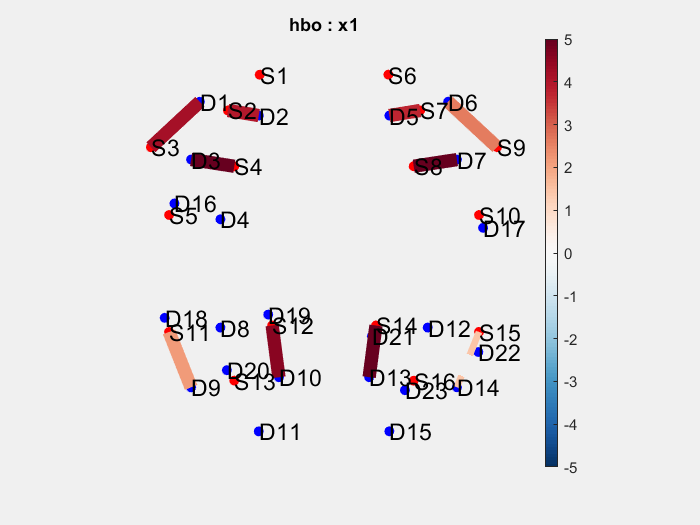

ans =   Figure (1: hbo : x1) with properties:

      Number: 1
        Name: 'hbo : x1'
       Color: [0.9400 0.9400 0.9400]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties



GroupStats.draw('tstat', [-5 5], 'p < 0.05')


% Contrast: Condition 2 vs Condition 1
c2_vs_1 = [-1, 1, 0]; % Contrast vector for condition 2 vs. condition 1
ContrastStats2_vs_1 = GroupStats.ttest(c2_vs_1);
ContrastStats2_vs_1.draw('tstat', [-5 5], 'p < 0.05');

disp(ContrastStats2_vs_1.table());
p5 = ContrastStats2_vs_1.table()

% Save the table to a CSV file
outputFile = '1st_half_contrast_ROI_AGG_clean.csv';            % Specify the output file name
writetable(p5, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);



## 2nd half

root_dir = 'C:\Users\pkell\OneDrive\Documents\fNIRS\pilot data\rel_match\v3\nirs';

% Load .nirs files
raw = nirs.io.loadDirectory(root_dir, {'subject'});

% Trim each file to only keep the second half of the recording
for i = 1:length(raw)
    full_time = raw(i).time(end) - raw(i).time(1);
    midpoint = raw(i).time(1) + full_time / 2;

    % Crop data and stimulus
    raw(i).data = raw(i).data(raw(i).time > midpoint, :);
    raw(i).time = raw(i).time(raw(i).time > midpoint);

    stim_names = fieldnames(raw(i).stimulus);
    for s = 1:length(stim_names)
        stimname = stim_names{s};
        stim_table = raw(i).stimulus.(stimname);

        % Keep only stim with onset in second half
        if isfield(stim_table, 'onset')
            raw(i).stimulus.(stimname) = stim_table(stim_table.onset > midpoint, :);
        end
    end
end

% Display stim names
available_stims = nirs.getStimNames(raw);
disp('Available stim names:');
disp(available_stims);

% Keep desired stimulus channels
j = nirs.modules.KeepStims();
j.listOfStims = {'stim_channel1', 'stim_channel2'};  % Update if needed
raw = j.run(raw);

% Rename stim channels
j = nirs.modules.RenameStims();
j.listOfChanges = {
   'stim_channel1', '1';
   'stim_channel2', '1';
};
raw = j.run(raw);
disp('Stim names after renaming:');
disp(nirs.getStimNames(raw));

% Set duration for all stimuli
stimNames = unique(nirs.getStimNames(raw));
for s = 1:length(stimNames)
    raw = nirs.design.change_stimulus_duration(raw, stimNames{s}, 36);
end

% Run QT-NIRS for quality check
j = nirs.modules.QT();
j.qThreshold = 0.7; j.fCut = [0.5 2.5]; j.sciThreshold = 0.6; j.pspThreshold = 0.1;
ScansQuality = j.run(raw);

% Preprocessing pipeline
j = nirs.modules.Resample(); j.Fs = 1.5; raw = j.run(raw);
j = nirs.modules.OpticalDensity(); raw = j.run(raw);
j = nirs.modules.TDDR(); raw = j.run(raw);
j = nirs.modules.BeerLambertLaw(); hb = j.run(raw);

% Channel pruning based on QT
Hb_pruned = hb;
for i = 1:length(hb)
    hb(i) = hb(i).sorted({'source', 'detector', 'type'});
    bad_idx = find(ScansQuality(i).qMats.MeasListAct == 0);
    fprintf('Scan:%i #BadChannels:%i\n', i, length(bad_idx)/2);
    Hb_pruned(i).data(:, bad_idx) = NaN;
end

% --- ROI Aggregation ---
roi_definitions = struct( ...
    'Left_RLPFC', [1 1; 1 2; 2 1; 2 2], ...
    'Left_DLPFC', [4 3; 4 2; 4 4; 5 3; 5 4; 5 16; 2 3], ...
    'Left_VLPFC', [3 1; 3 3], ...
    'Left_Sup_Parietal', [12 8; 12 10; 13 10; 13 20; 12 19], ...
    'Left_Inf_Parietal', [11 9; 11 8; 13 8; 13 9; 13 11; 11 18], ...
    'Right_RLPFC', [6 5; 6 6; 7 5; 7 6], ...
    'Right_DLPFC', [7 7; 8 5; 8 7; 10 7; 10 17], ...
    'Right_VLPFC', [9 7; 9 6], ...
    'Right_Sup_Parietal', [14 12; 14 13; 14 21; 16 13], ...
    'Right_Inf_Parietal', [15 12; 15 14; 16 12; 16 14; 16 15; 15 22; 16 23] ...
);

% ROI-specific dummy source-detector assignments for proper plotting
roi_sd_lookup = struct( ...
    'Left_RLPFC', [2, 2], ...
    'Left_DLPFC', [4, 3], ...
    'Left_VLPFC', [3, 1], ...
    'Left_Sup_Parietal', [12, 10], ...
    'Left_Inf_Parietal', [11, 9], ...
    'Right_RLPFC', [7, 5], ...
    'Right_DLPFC', [8, 7], ...
    'Right_VLPFC', [9, 6], ...
    'Right_Sup_Parietal', [14, 13], ...
    'Right_Inf_Parietal', [15, 14] ...
);

for i = 1:length(Hb_pruned)
    dat = Hb_pruned(i);
    new_data = [];
    roi_labels = {};
    sources = [];
    detectors = [];

    for roi = fieldnames(roi_definitions)'
        roi_name = roi{1};
        pairs = roi_definitions.(roi_name);
        roi_ts = nan(size(dat.data, 1), size(pairs, 1));

        for p = 1:size(pairs, 1)
            src = pairs(p, 1);
            det = pairs(p, 2);
            idx = find(dat.probe.link.source == src & ...
                       dat.probe.link.detector == det & ...
                       strcmpi(dat.probe.link.type, 'hbo'));
            if ~isempty(idx)
                roi_ts(:, p) = dat.data(:, idx(1));
            end
        end

        % Average across channels in the ROI
        new_data = [new_data, nanmean(roi_ts, 2)];
        roi_labels = [roi_labels, roi_name];

        % Use fixed dummy source-detector pair
        sources(end+1) = roi_sd_lookup.(roi_name)(1);
        detectors(end+1) = roi_sd_lookup.(roi_name)(2);
    end

    % Replace data with aggregated ROI signals
    dat.data = new_data;

    % Construct new probe link table with correct dummy S-D mapping
    new_link = table();
    new_link.source = sources';
    new_link.detector = detectors';
    new_link.type = repmat({'hbo'}, length(roi_labels), 1);
    new_link.name = roi_labels';
    dat.probe.link = new_link;

    Hb_pruned(i) = dat;
end

% label short channels
%j = nirs.modules.LabelShortSeperation();
%Hb_pruned = j.run(hb)

% Apply prewhitening using AR-IRLS - no short channels 
j = nirs.modules.AR_IRLS();
SubjStats = j.run(Hb_pruned);

disp(SubjStats.table());
p3 = SubjStats.table()

% Save the table to a CSV file
outputFile = '2nd_glm_result_subjectlevel_ROI_AGG_tvr_clean.csv';            % Specify the output file name
writetable(p3, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);


%% Compute subject-level contrast: condition 1 vs 2
% Define the contrast vector
contrast = [1 -1];  % condition 1 > condition 2

contrast_results = [];
for i = 1:length(SubjStats)
    c = SubjStats(i).ttest(contrast);
    tbl = c.table();
    tbl.subject = repmat(string(SubjStats(i).description), height(tbl), 1);
    contrast_results = [contrast_results; tbl];
end

% Display final subject-level contrast table
%contrast_output = contrast_results(:, {'subject', 'channel', 'type', 'beta', 'tstat', 'p'});
disp(contrast_results);

% Save contrast results
writetable(contrast_results, '2nd_half_subject_level_contrasts_ROIAGG_clean.csv');
disp('Contrast results saved to 2nd_half_subject_level_contrasts.csv');


%use chroma and channel as fixed effects not group (no group)
j = nirs.modules.MixedEffects();
j.formula = 'beta ~ -1 + cond + (1|subject)';
j.dummyCoding = 'full';
GroupStats = j.run(SubjStats);

disp(GroupStats.table());
p1 = GroupStats.table()

% Save the table to a CSV file
outputFile = '2nd_half_GLM_GROUP_ROI_AGG_tvr_clean.csv';            % Specify the output file name
writetable(p1, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);

GroupStats.draw('tstat', [-5 5], 'p < 0.05')


% Contrast: Condition 2 vs Condition 1
c2_vs_1 = [-1, 1, 0]; % Contrast vector for condition 2 vs. condition 1
ContrastStats2_vs_1 = GroupStats.ttest(c2_vs_1);
ContrastStats2_vs_1.draw('tstat', [-5 5], 'p < 0.05');

disp(ContrastStats2_vs_1.table());
p5 = ContrastStats2_vs_1.table()

% Save the table to a CSV file
outputFile = '2nd_half_contrast_ROI_AGG_clean.csv';            % Specify the output file name
writetable(p5, outputFile);      % Save the table as a CSV
disp(['GLM results saved to ', outputFile]);

